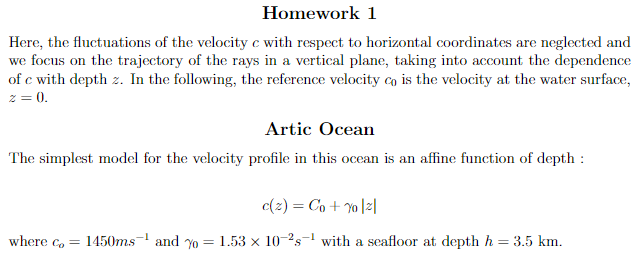

clear
clc

% Initial conditions
Co = 1450;
gamma = 1.53e-2;
h = 3500 ; % maximun depth

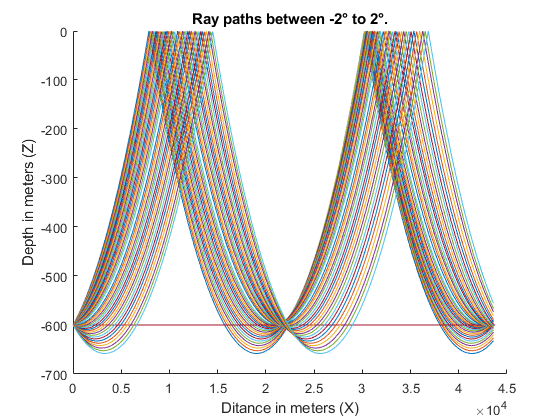

% Parameter difinition
zs = 600;
total_period = 30;
dt = 0.01;
t = 0:dt:total_period;
angle = -2:0.1:2;
% angle = [-2 2]

n_rows = length(angle);
n_columns = length(t);

ray_matrix = zeros(n_rows, n_columns);

for i = 1:length(angle)
    
    x = zeros(size(t));
    x(1) = 0;
    
    z = zeros(size(t));
    z(1) = zs;
    
    theta = zeros(size(t));
    theta(1)  = angle(i)*pi/180;
    
    c = zeros(size(t));
    c(1)=velocity(z(1),Co,gamma);
    
    ray_matrix(:,1) = z(1);
    
    for j = 2:length(t)
        
        x(j) = x(j-1) + c(j-1) * dt * cos(theta(j-1));
        z(j) = z(j-1) + c(j-1) * dt * sin(theta(j-1));
        c(j) = velocity(z(j),Co,gamma);
        
        % Snail constant
        K = cos(theta(j-1))*c(j)/c(j-1);
        
        if K <= 1
            
            theta(j) = sign(theta(j-1))*acos(K);
            
        else
    
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end
        
    
        if (z(j) <= 0) || (z(j)>=h)
            
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end   

        ray_matrix(i,j) =  z(j);
        
    end
    
    hold on
    plot(x,-ray_matrix(i,:))
    
end

title('Ray paths between -2° to 2°.')
xlabel('Ditance in meters (X)') 
ylabel('Depth in meters (Z)') 
hold off

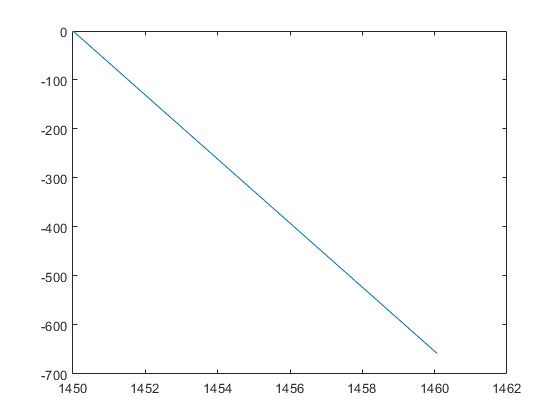

plot(c,-ray_matrix(41,:))

What is the maximun depth reached by this beam?

max_depth = max(ray_matrix(:))

max_depth = 658.1329

[ii,jj] = find(ray_matrix == max_depth);

angle(ii)

ans =     -2    -2


The max maximun depth reached by the beam is $658\ldotp 1329\;$meters with $\theta =-2°$.

function c = velocity(z, Co, gamma)

    c = Co + gamma*abs(z);
 
end